## `Model`

`(h=0.01)`

% A = [0.9904 0 0; 0 1 0.01; -0.00000335 -0.0254 0.9985];
% B = [4.1334; 0; 0];
% C = [1 0 0; 0 1 0];
D = [0;0];
h = 0.01;

## Test 1

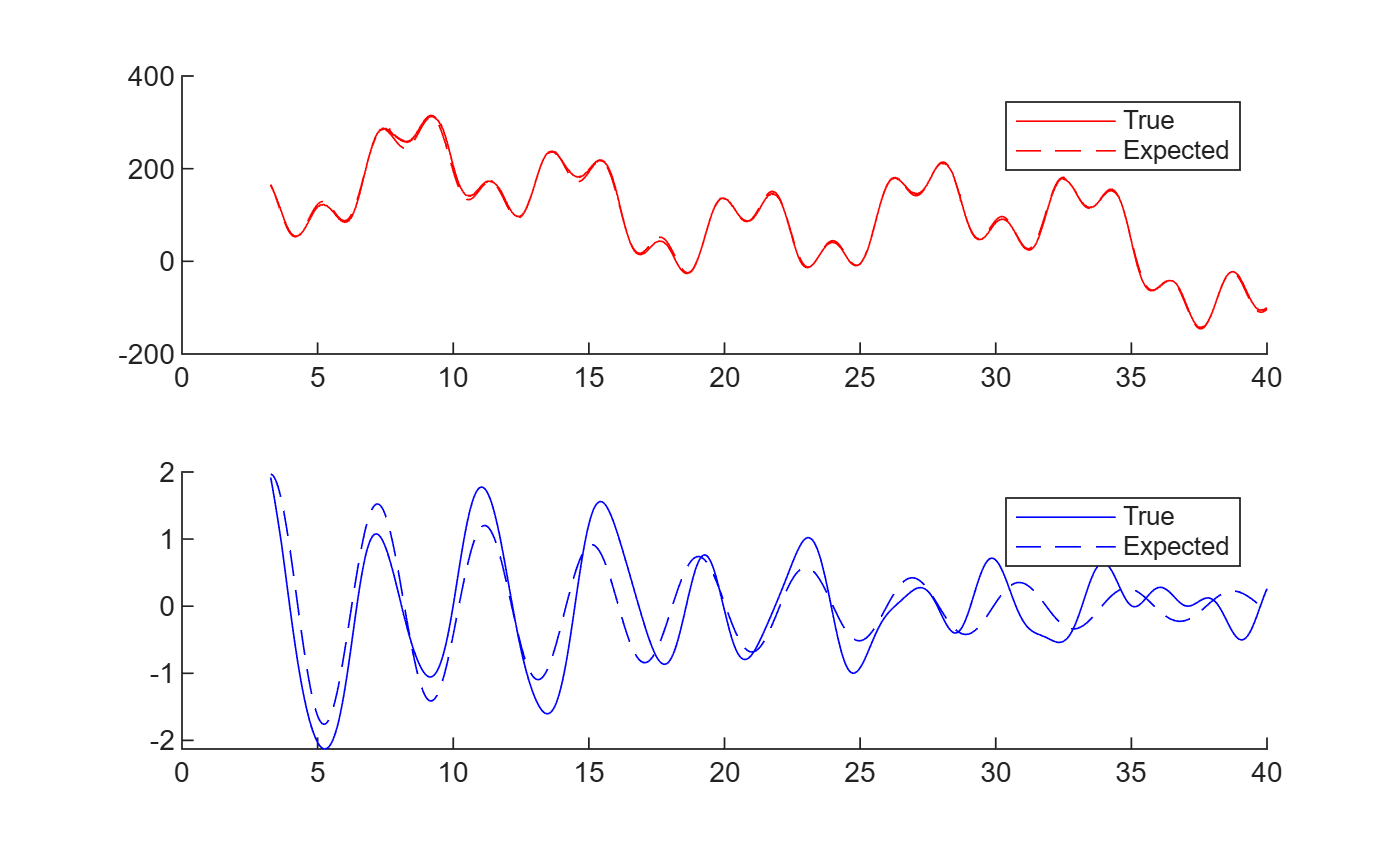

load('Drop_+_sines.mat')
y1 = angular_velocity.data;
y2 = pendulum_angle.data;
u = stim_input_1;

% figure;
% y2 = y2 + 2*pi*ones(N,1);
% plot(t, y2)

data_start = 328;
y1 = y1(data_start:end);
y2 = y2(data_start:end);
t = t(data_start:end);
u = u(data_start:end);

N = length(t);

% Data pre-processing
y2 = y2 + 2*pi;

y = zeros(N*2,1);
for i = 1:N
    y((i-1)*2+1:i*2) = [y1(i); y2(i)];
end

%theta0 = [165; 2; 0];
%x0 = find_initial_condition(A,B,C,u,y, theta0);
x0 = [165.6818; 1.9661; -0.0478];

[yhat,~] = simsystem_y_as_vec(A,B,C,D,x0,u);
% [yhat,~] = simsystem_nonlinearised(A,B,C,D,x0,u);
y1hat = zeros(N,1); y2hat = zeros(N,1);
for i = 1:N
    y1hat(i) = yhat((i-1)*2+1);
    y2hat(i) = yhat(i*2);
end

figure;
tiledlayout(2,1);
nexttile
hold on
plot(t,y1, 'color', 'red', 'LineStyle', '-');
plot(t,y1hat, 'color', 'red', 'LineStyle', '--');
legend('True', 'Expected')

nexttile
hold on
plot(t,y2, 'color', 'blue', 'LineStyle', '-');
plot(t,y2hat, 'color', 'blue', 'LineStyle', '--');
legend('True', 'Expected');

## Test 2

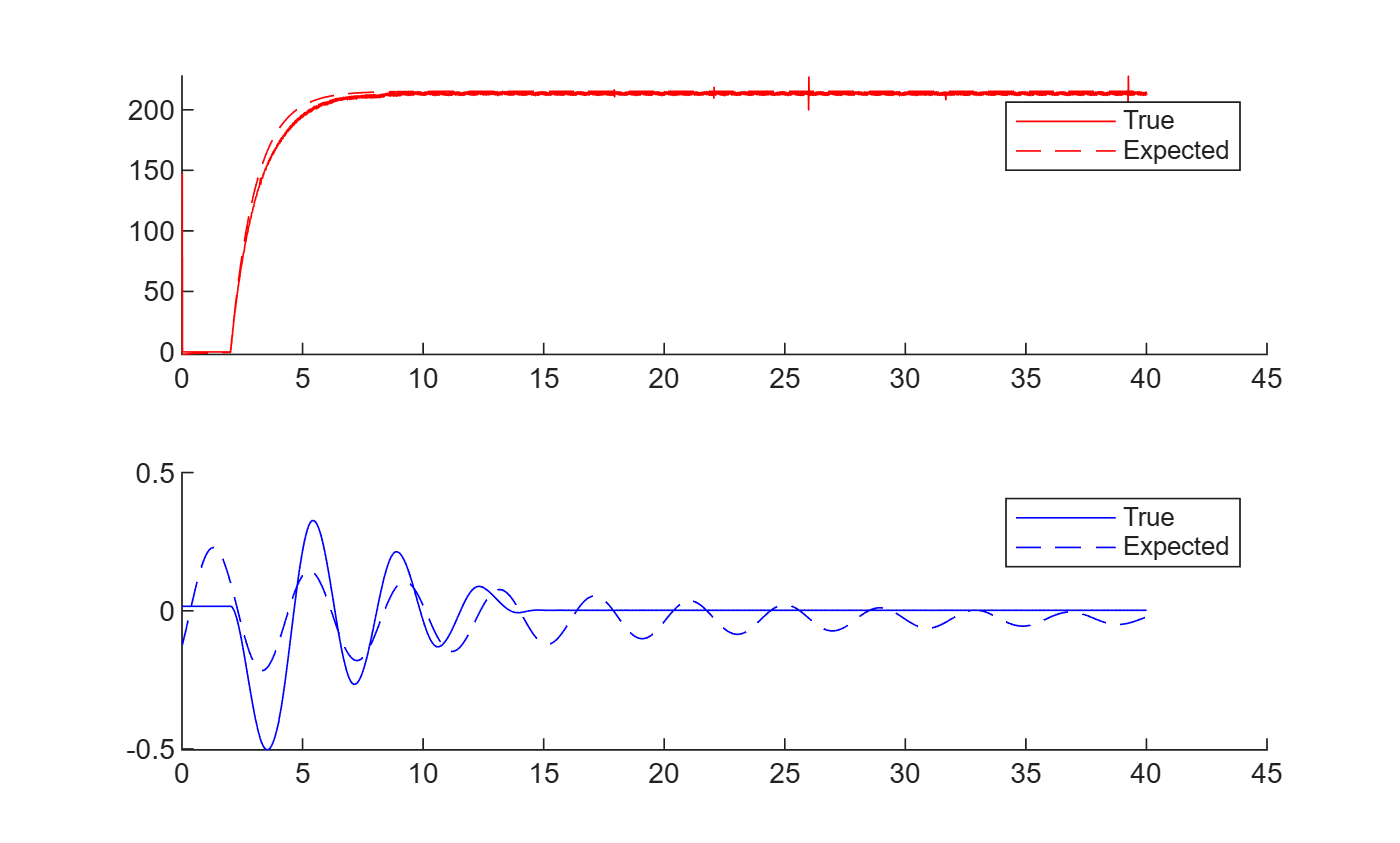

clearvars -except A B C D h

load('step_response.mat')
y1 = angular_velocity.data;
y2 = pendulum_angle.data;
u = squeeze(control.data);
N = length(u);
t = h:h:h*N;

y = zeros(N*2,1);
for i = 1:N
    y((i-1)*2+1:i*2) = [y1(i); y2(i)];
end

theta0 = [1; 0; 0];
x0hat = find_initial_condition(A,B,C,u,y, theta0);
x0 = [1; 0; 0];


[yhat,~] = simsystem_y_as_vec(A,B,C,D,x0hat,u);
% [yhat,~] = simsystem_nonlinearised(A,B,C,D,x0hat,u);
y1hat = zeros(N,1); y2hat = zeros(N,1);
for i = 1:N
    y1hat(i) = yhat((i-1)*2+1);
    y2hat(i) = yhat(i*2);
end

figure;
tiledlayout(2,1);
nexttile
hold on
plot(t,y1, 'color', 'red', 'LineStyle', '-');
plot(t,y1hat, 'color', 'red', 'LineStyle', '--');
legend('True', 'Expected')

nexttile
hold on
plot(t,y2, 'color', 'blue', 'LineStyle', '-');
plot(t,y2hat, 'color', 'blue', 'LineStyle', '--');
legend('True', 'Expected');

## Test 3

clearvars -except A B C D h

load('Input_1_response.mat')
y1 = angular_velocity.data;
y2 = pendulum_angle.data;
u = stim_input_1;
N = length(t);



y = zeros(N*2,1);
for i = 1:N
    y((i-1)*2+1:i*2) = [y1(i); y2(i)];
end

theta0 = [1; 0; 0];
x0hat = find_initial_condition(A,B,C,u,y, theta0)

x0hat =    16.3968
    0.0283
   -0.1696


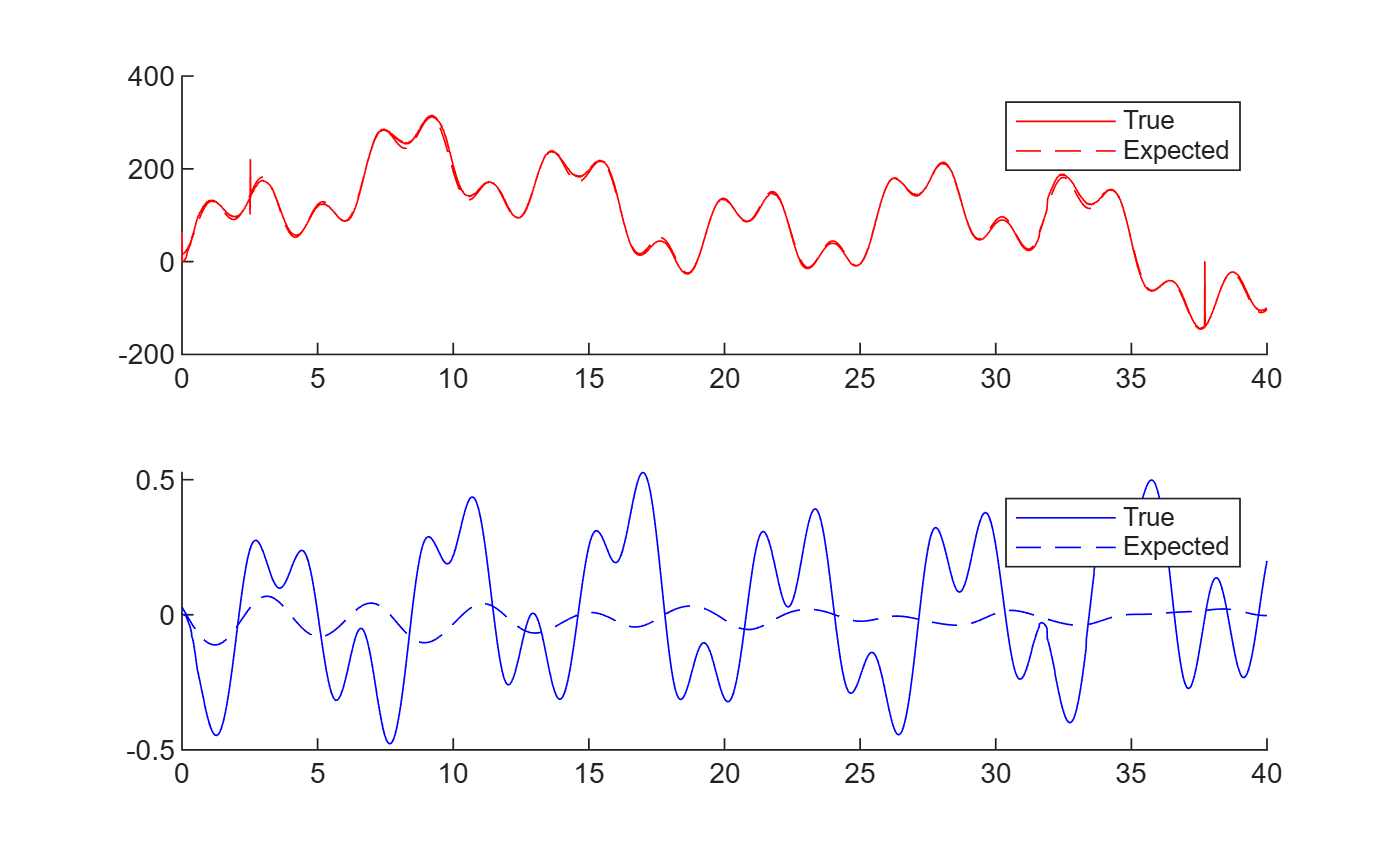

x0 = [1; 0; 0];


[yhat,~] = simsystem_y_as_vec(A,B,C,D,x0hat,u);
% [yhat,~] = simsystem_nonlinearised(A,B,C,D,x0hat,u);
y1hat = zeros(N,1); y2hat = zeros(N,1);
for i = 1:N
    y1hat(i) = yhat((i-1)*2+1);
    y2hat(i) = yhat(i*2);
end

figure;
tiledlayout(2,1);
nexttile
hold on
plot(t,y1, 'color', 'red', 'LineStyle', '-');
plot(t,y1hat, 'color', 'red', 'LineStyle', '--');
legend('True', 'Expected')

nexttile
hold on
plot(t,y2, 'color', 'blue', 'LineStyle', '-');
plot(t,y2hat, 'color', 'blue', 'LineStyle', '--');
legend('True', 'Expected');

## Initial Condition Finder

function x0 = find_initial_condition(A,B,C,u,y, theta0)
    theta = theta0;
    lambda = 0;
    maxiter = 5;
    p = 3; % Number of parameters (n)
    D = [0;0];
    
    % initialize
    converged = false;
    maxiter_reached = false;
    iter = 1;
    
    while ~converged && ~maxiter_reached 
    
        x0 = theta;
        [yhat, xhat] = simsystem_y_as_vec(A, B, C, D, x0, u);
        E = y - yhat;
        psi = psi_fun(xhat, A, C);
        N_E = length(E);
        J = 2/N_E * psi' * E; % Jacobian
        N_H = size(psi,1);
        H = 2/N_H * (psi' * psi); % Hessian
    
        invLM = (H + lambda * eye(p))\eye(p); %Levenberg-Marquardt singularity inverse
        theta_new = theta - invLM * J;
    
        
        % Check convergence
        if norm(theta_new - theta) < 1e-6
            converged = true; 
        elseif iter == maxiter 
            maxiter_reached = true; 
            warning('Maximum iterations reached'); 
        end
        theta = theta_new; 
        iter = iter + 1;
    end
end



function psi = psi_fun(xhat, A, C)

% Dimensions
n = 3; l = 2;

dx01 = [1; 0; 0];
dx02 = [0; 1; 0];  
dx03 = [0; 0; 1];

N = size(xhat,1); 
p = 3; % 11 sub-parameters of theta

dy = zeros(l,p);
psi = zeros((N-1)*l,p);

dx=[dx01 dx02 dx03];
for k = 2:N % xhat is 0 - N-1, 
    % dy / psi update
    for i = 1 : p
        dy(:,i) = C * dx(:,i);
    end
    psi((k-l)*l+1:(k-l)*l+l,:) = -dy; % psi is relative to -dyhat

    % dx update

    % x0 parameters
    dx(:,1) = A * dx(:,1);
    dx(:,2) = A * dx(:,2);
    dx(:,3) = A * dx(:,3);

end
psi = [zeros(2,p) ; psi]; % How to deal with dyhat0?
end



function [y,x] = simsystem_y_as_vec(A,B,C,D,x0,u)

N = length(u);
n = length(x0);
l = size(C,1);
x = zeros(n, N);
y = zeros(l*N,1);

x(:,1) = x0;
y(1:2) = C * x(:,1) + D * u(1);

for k = 2:N
    x(:,k) = A * x(:,k-1) + B * u(k-1);
    y((k-1)*l+1:k*l) = C * x(:,k) + D * u(k);
end

x = x';
end

function [y,x] = simsystem_nonlinearised(A,B,C,D,x0,u)

N = length(u);
n = length(x0);
l = size(C,1);
x = zeros(n, N);
y = zeros(l*N,1);

x(:,1) = x0;
y(1:2) = C * x(:,1) + D * u(1);

% Convert from linearised
A_sin = [0 0 0; 0 0 0; 0 A(3,2) 0];
A(3,2) = 0;

for k = 2:N
    x(:,k) = A * x(:,k-1) + B * u(k-1) + A_sin * sin(x(:,k-1));
    y((k-1)*l+1:k*l) = C * x(:,k) + D * u(k);
end

x = x';
end